# **Assignment 1- Finite Elements Method 1D**

clc
clear
close all

## **Part 1 **

#### **1.1 Boundary Value Problem (BVP)**

% Symbolic variables
syms E A L g real % Constants
syms x real % Position variable
syms u(x) % Displacement function

% Constants definitions
rho = pi^3/L^2;
s = g*pi^4/L^2;
F = A*E*g*pi^2/L;
r = (x/L)^2;

% Distributed force
q = E*(rho*u-s*r);

% Hooke's law (We don't need to define them as symbolic)
epsilon = diff(u,x);
sigma = E*epsilon;

% Equilibrium
eq1 = diff(sigma,x)+q==0;

% Boundary conditions
cond1 = u(0) == -g; % Displacement 
du_dx_L = diff(u,x);
cond2 = A*E*subs(du_dx_L,x,L) == F; % Force

% General solution 
u_sol = dsolve(eq1, cond1, cond2);
u_sol_simp = vpa(u_sol,4);


**1.2 Exact Solution**

% Apply numeric values
L_val=1;
g_val=0.01;

% Substitute
u_sol_val=(subs(u_sol,[g L], [g_val, L_val]));
u_exact=vpa(u_sol_val,5);

% Plot of the exact solution
figure
colors = lines(8); % Define the colors vector
fplot(u_exact*1000, [0 L_val], 'Color', colors(2,:), 'LineWidth',2) % Converted to millimetres: *1000
xlabel('Position, $x$ [m]', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
ylabel('Displacement, $u$ [mm]', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
grid on
title('Exact solution of the BVP', 'FontSize', 18, 'FontWeight', 'bold');

**1.3, 1.4, 1.5 Variational Method**

b=g_val*pi^2/L_val; % Boundary conditions
s_val = subs(s,[g L],[g_val L_val]); % Constant
rho_val=subs(rho,L,L_val); % Constant
f = -s_val*x^2/L_val^2; % Source function --> Function in the ODE



% Basis Functions (polynomial functions)

n_end = 6; % Last exponent (x^{n_end})
N = cell(1, n_end); % Inicializar un arreglo de celdas para almacenar cada vector

for i = 1:n_end  % Loop from 1 until n_end 
    N{i} = x.^(0:i);  % Guardar cada vector en una celda de N
end
% N = [1, x, x^2, x^3,x^4, x^5, x^6]; % Basis functions. Resolution functions (3rd order), we have to obtain the amplitudes (constants d)

for i = 1:length(N)
    u_approx{i} = galerkin_solve_Prac1(N{i},f,b,g_val,L_val,rho_val);
    vpa(u_approx{i},4);
    % Plot for every N{i}
    % figure(i+1);  
    % hold on;
    % xlabel('Position, $x$ [m]', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
    % ylabel('Displacement, $u$ [mm]', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
    % title('Exact and approximate solution of the BVP', 'FontSize', 18, 'FontWeight', 'bold');
    % fplot(u_exact*1000, [0 L_val], 'Color', colors(2,:), 'LineWidth',2) % Converted to millimetres: *1000
    % fplot(u_approx{i}*1000, [0 L_val], 'Color', colors(1,:), 'LineWidth',2) % Converted to millimetres: *1000
    % legend('Exact', ['Galerkin N = ', char(N{i})],'Location','southeast');
    % hold off;
end


**1.6,1.7 Finite linear element basis**

%General relations
syms xi x1 x2 he rho
Ne_xi = 1/2*[1-xi, 1+xi];
x = Ne_xi*[x1 ,x2]';
Be_xi = diff(Ne_xi,xi);
%Matrix K expression
ke=1/he*int(Be_xi'*Be_xi,xi,-1,1)+rho*he/2*int(Ne_xi'*Ne_xi,xi,-1,1);

%Force element expression
fe=int(Ne_xi.'*x^2,xi,-1,1);

%Discretitzation
x0 = 0; % First node
xF = L_val; % Last node
n_elem_vect = [5 10 20 40]; % Number of elements


for n=1:length(n_elem_vect)
    n_elem=n_elem_vect(n);
    COOR = linspace(x0,xF,n_elem+1)'; % Equispaced vector of nodes
    CN = zeros(n_elem,2); % Connectivty matrix
    for i=1:n_elem
        CN(i,1) = i;
        CN(i,2) = i+1;
    end
    
    K = AssemblyK(COOR, CN, rho_val);
    F = AssemblyF(COOR, CN, s_val, L_val,g_val);
    r = 1; l = 2:(n_elem+1); % Freedom degrees. known/unkown coeficients
    dl = K(l,l)\(F(l)+K(l,r)*g_val); % Solving equations system
    d=[-g_val, dl'];
    
    % figure
    % hold on
    % plot(COOR,(d*1000),'Color', colors(1,:), 'LineWidth',2)
    % fplot(u_exact*1000, [0 L_val], 'Color', colors(2,:), 'LineWidth',2) % Converted to millimetres: *1000
    % 
    % xlabel('Position, $x$ [m]', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
    % ylabel('Displacement, $u$ [mm]', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
    % title('Exact and finite element solution of the BVP', 'FontSize', 18, 'FontWeight', 'bold');
    % legend(['Number of elements = ', num2str(n_elem)], 'Exact', 'Location','southeast');
end

## Part 2

**Convergence**

syms x real

n_elem_vect = 5:5:200; % Number of elements 

% Gauss quadrature for m = 3
xi_g = [sqrt(3/5) -sqrt(3/5) 0]; % Positions
w = [5/9 5/9 8/9]; % Weights

u_exact_diff = diff(u_exact); % Calculation of u' (exact)

Ne_xi=@(xi) (1/2)*[1-xi 1+xi]; % Redefinition of Ne as a function handle

% Inicialization of error convergence vectors
Error_u = zeros(length(n_elem_vect),1);
Error_Du = zeros(length(n_elem_vect),1); 
elem_size = zeros(length(n_elem_vect),1);

% Error calculation loop
for n = 1:length(n_elem_vect)
    n_elem = n_elem_vect(n);
    COOR = linspace(x0,L_val,n_elem+1)'; % Equispaced vector of nodes
    CN = zeros(n_elem,2); % Connectivty matrix
    for i = 1:n_elem
        CN(i,1) = i;
        CN(i,2) = i+1;
    end
    
    K = AssemblyK(COOR, CN, rho_val);
    F = AssemblyF(COOR, CN, s_val, L_val, g_val);
    r = 1; l = 2:(n_elem+1); % Freedom degrees. known/unkown coeficients
    dl = K(l,l)\(F(l)+K(l,r)*g_val); % Solving equations system
    d = [-g_val, dl'];
    
    error_u = 0; 
    error_du = 0;

    for e = 1:n_elem
        COORe = [COOR(CN(e,1)); COOR(CN(e,2))]; % Physical coordinates of u
        de = [d(CN(e,1));d(CN(e,2))]; % Nodal values of u
        he = COOR(CN(e,2))-COOR(CN(e,1)); % Element size
        B = 1/he*[-1 1]; % Derivative of the shape function

        % Integration by Gauss quadrature
        for m = 1:3
            u_h = Ne_xi(xi_g(m))*de; % Value of the FEM function
            u_h_diff = B*de; % Ídem for the derivative
            xF = Ne_xi(xi_g(m))*COORe; % Physical coordinate of xi_g
            u_Exact = subs(u_exact, x, xF); % Evaluation of the exact function at the point
            u_Exact = double(u_Exact);
            u_Exact_diff = subs(u_exact_diff, x, xF); % Ídem for the derivative
            u_Exact_diff = double(u_Exact_diff);
            % Error computation
            error_u = error_u+he/2*(w(m)*(u_Exact-u_h)^2);
            error_du = error_du+he/2*(w(m)*(u_Exact_diff-u_h_diff)^2);
        end

    end

    Error_u(n) = sqrt(error_u);
    Error_Du(n) = sqrt(error_du); 
    elem_size(n) = he; 

end

% Linear regression functions

log_elem_size = log(elem_size);
log_Error_u = log(Error_u);
log_Error_Du = log(Error_Du);

p1 = polyfit(log_elem_size,log_Error_u,1);
p2 = polyfit(log_elem_size,log_Error_Du,1);

p_u = polyval(p1, log_elem_size);
p_Du = polyval(p2, log_elem_size);

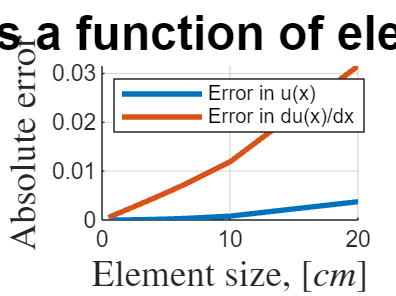

% Error plots
figure
hold on
plot(elem_size*100, Error_u,'Color', colors(1,:), 'LineWidth',2)
plot(elem_size*100, Error_Du,'Color', colors(2,:), 'LineWidth',2)
xlabel('Element size, $[cm]$', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
ylabel('Absolute error', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
title('Error as a function of element size', 'FontSize', 18, 'FontWeight', 'bold');
grid on
legend('Error in u(x)','Error in du(x)/dx', 'Location','northwest');
hold off

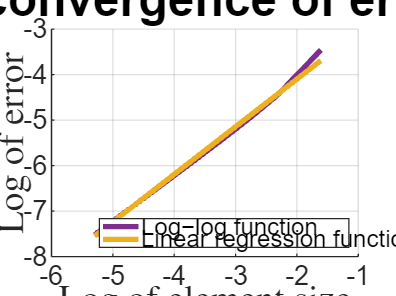


figure
hold on
plot(n_elem_vect, Error_u,'Color', colors(1,:), 'LineWidth',2)
plot(n_elem_vect, Error_Du,'Color', colors(2,:), 'LineWidth',2)
xlabel('Number of Elements', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
ylabel('Absolute error', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
title('Error as a function of number of elements', 'FontSize', 18, 'FontWeight', 'bold');
grid on
legend('Error in u(x)','Error in du(x)/dx', 'Location','northwest');
hold off

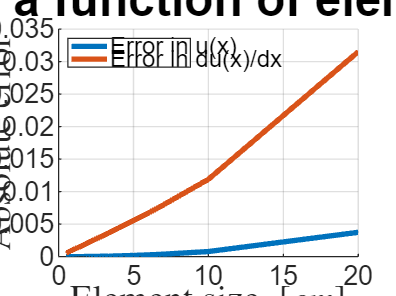


figure
hold on
plot(log_elem_size, log_Error_u,'Color', colors(4,:), 'LineWidth',2)
plot(log_elem_size, p_u,'Color', colors(3,:), 'LineWidth',2)
xlabel('Log of element size', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
ylabel('Log of error', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
title('Logarithmic convergence of error in u(x)', 'FontSize', 18, 'FontWeight', 'bold');
grid on
legend('Log−log function',sprintf('Linear regression function: %s*x %s', num2str(p1(1)), num2str(p1(2))), 'Location','southeast');
hold off


figure
hold on
plot(log_elem_size, log_Error_Du,'Color', colors(4,:), 'LineWidth',2)
plot(log_elem_size, p_Du,'Color', colors(3,:), 'LineWidth',2)
xlabel('Log of element size', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
ylabel('Log of error', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
title('Logarithmic convergence of error in du(x)/dx', 'FontSize', 18, 'FontWeight', 'bold');
grid on
legend('Log−log function',sprintf('Linear regression function: %s*x %s', num2str(p2(1)), num2str(p2(2))), 'Location','southeast');
hold off